## Modelo RST del robot ABB IRB 1600

### Modelo dh-mod RST

L1=0.487;
L2=0.15;
L3=.488;
L4=0.6;
L5=0.05;
%Los parámetros dhmod se deben poner en el orden a alpha d theta 
mdhparams=[0	0	L1	0;
L2	pi/2	0	0;
L3	0	0	0	;
0	pi/2	L4	0	;
0	-pi/2	0	0	;
0	pi/2	0	0	];
%setFixedTransform(jointObj,mdhparams,"mdh")
%Se crea un objeto rigidbodytree que será el modelo de nuestro robot
clear robot
robot = rigidBodyTree("MaxNumBodies",7,"DataFormat","column");
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');

%se definen las transformadas, una a una teniendo encuenta 
setFixedTransform(jnt1,mdhparams(1,:),'mdh');
body1.Joint = jnt1;

addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition=pi/2;
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');

setFixedTransform(jnt2,mdhparams(2,:),'mdh');
setFixedTransform(jnt3,mdhparams(3,:),'mdh');
setFixedTransform(jnt4,mdhparams(4,:),'mdh');
setFixedTransform(jnt5,mdhparams(5,:),'mdh');
setFixedTransform(jnt6,mdhparams(6,:),'mdh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')
showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


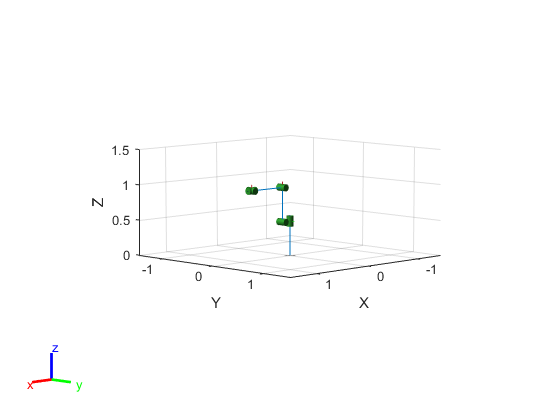

%show(robot,randomConfiguration(robot),'Frames',"on");
%Se crean cilindros de colisión:
collisionObj = collisionCylinder(0.05,0.15);
addCollision(robot.Bodies{1},collisionObj)
addCollision(robot.Bodies{2},collisionObj)
addCollision(robot.Bodies{3},collisionObj)
addCollision(robot.Bodies{4},collisionObj)
addCollision(robot.Bodies{5},collisionObj)
addCollision(robot.Bodies{6},collisionObj)
% for i = 1:robot.NumBodies
%     if i > 6 && i < 10
%         % Skip these bodies.
%     else
%         addCollision(robot.Bodies{i},collisionObj)
%     end
% end
show(robot,homeConfiguration(robot),'Collisions','on','Visuals','off');
xlim([-1.5 1.5])
ylim([-1.5 1.5])
zlim([0 1.5])

%Se guardan los modelos en el archivo de variables global
save("LAB2_variables")
